# `INVERTED PENDULUM`

clc; clear; close all;

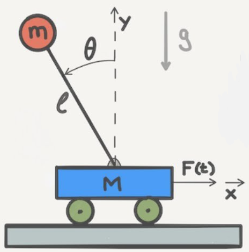

## `System Properties:`

m =   1; % small mass
M =   5; % cart
L =   2; % pendulum arm length
g = -10; % gravitational accel
d =   1; % friction

## `Solver:`

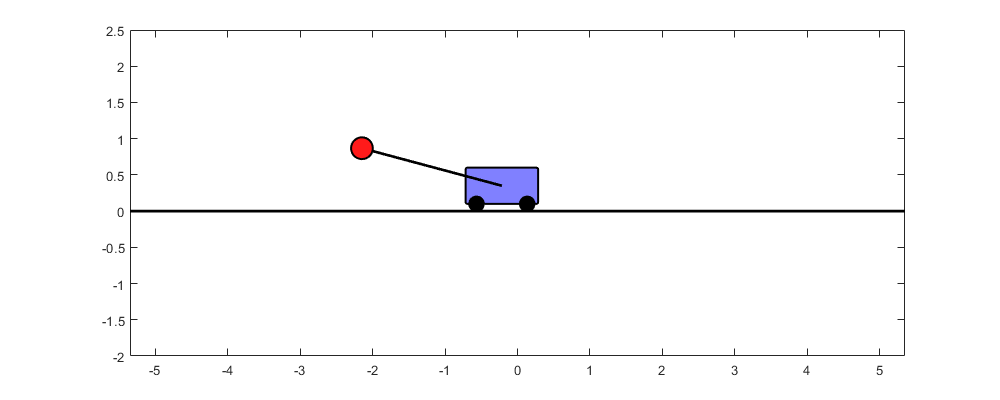

u = 0; % System is not under control now.

tspan = 0:.1:5;
x0 = [0; 0; pi; .5];
[t,x] = ode45(@(t,x)cartpend(x,m,M,L,g,d,u),tspan,x0);

for k = 1:length(t)
    drawpend(x(k,:),m,M,L);
end

## `Linerarized System:`

A = [0 1 0 0;
     0 -d/M -m*g/M 0;
     0 0 0 1;
     0 -d/(M*L) -(m+M)*g/(M*L) 0];

B = [0; 1/M; 0; 1/(M*L)];


## `Stability:`

fprintf('Eigen values of uncontrolled linearized system are:\n');disp(eig(A));

Eigen values of uncontrolled linearized system are:
         0
   -2.4674
   -0.1665
    2.4339



fprintf('If there is a right hand side pole (any positive value), then uncontrolled system is unstable.')

If there is a right hand side pole (any positive value), then uncontrolled system is unstable.

## `Controllability:`

if rank(ctrb(A,B)) == length(x0)
fprintf("System is controllable.")
else
fprintf("System is uncontrollable.")
end

System is controllable.

## `Pole Placement:`

desired_eigs = [-1.1; -1.2; -1.3; -1.4];
K = place(A,B,desired_eigs);

fprintf('K = \n'); disp(K);

K = 
   -2.4024   -8.7500  158.3048   65.5000



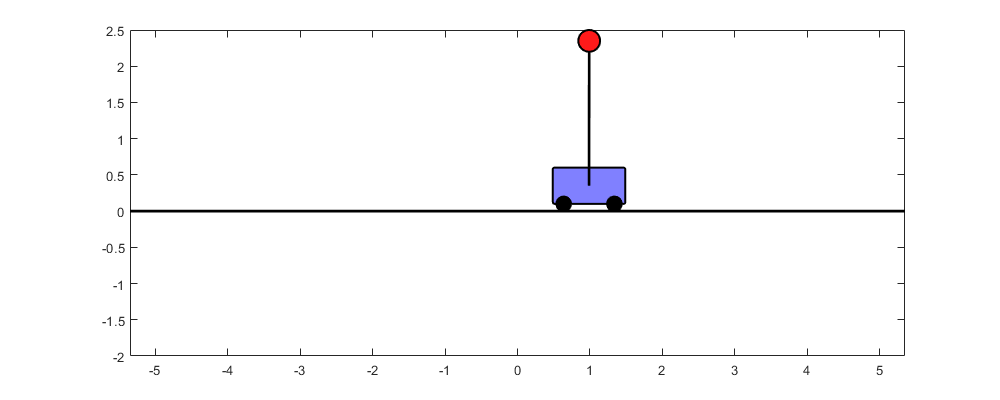


x0 = [-1; 0; 0.8*pi; .5];

x_desired = [1; 0; pi; 0];

tspan = 0:.1:15;
[t,x] = ode45(@(t,x)cartpend(x,m,M,L,g,d,-K*(x-x_desired)),tspan,x0); 
% u = K*(x-x0) here.

for k = 1:length(t)
    drawpend(x(k,:),m,M,L);
end

## `LINEAR QUADRATIC CONTROLLER (LQR):`

Q = [1 0 0 0;
     0 1 0 0;
     0 0 10 0;
     0 0 0 100];

R = 0.001;

K = lqr(A,B,Q,R,0);

fprintf('K = \n'); disp(K);

K = 
  -31.6228  -80.4636  900.1333  506.4064




x0 = [-1; 0; 0.8*pi; .5];

x_desired = [1; 0; pi; 0];

tspan = 0:.1:15;
[t,x] = ode45(@(t,x)cartpend(x,m,M,L,g,d,-K*(x-x_desired)),tspan,x0); 
% u = K*(x-x0) here.

for k = 1:length(t)
    drawpend(x(k,:),m,M,L);
end

## *Functions Used:*

function dx = cartpend(x,m,M,L,g,d,u)
Sx = sin(x(3));
Cx = cos(x(3));
D = m*L*L*(M+m*(1-Cx^2));

dx(1,1) = x(2);
dx(2,1) = (1/D)*(-m^2*L^2*g*Cx*Sx + m*L^2*(m*L*x(4)^2*Sx - d*x(2))) + m*L*L*(1/D)*u;
dx(3,1) = x(4);
dx(4,1) = (1/D)*((m+M)*m*g*L*Sx - m*L*Cx*(m*L*x(4)^2*Sx - d*x(2))) - m*L*Cx*(1/D)*u;
end

function drawpend(state,m,M,L)
x = state(1);
th = state(3);

% dimensions
W = 1*sqrt(M/5);  % cart width
H = .5*sqrt(M/5); % cart height
wr = .2;          % wheel radius
mr = .3*sqrt(m);  % mass radius

% positions
y = wr/2+H/2; % cart vertical position
pendx = x + L*sin(th);
pendy = y - L*cos(th);

plot([-10 10],[0 0],'k','LineWidth',2), hold on
rectangle('Position',[x-W/2,y-H/2,W,H],'Curvature',.1,'FaceColor',[.5 0.5 1],'LineWidth',1.5); % Draw cart
rectangle('Position',[x-.9*W/2,0,wr,wr],'Curvature',1,'FaceColor',[0 0 0],'LineWidth',1.5); % Draw wheel
rectangle('Position',[x+.9*W/2-wr,0,wr,wr],'Curvature',1,'FaceColor',[0 0 0],'LineWidth',1.5); % Draw wheel
plot([x pendx],[y pendy],'k','LineWidth',2); % Draw pendulum
rectangle('Position',[pendx-mr/2,pendy-mr/2,mr,mr],'Curvature',1,'FaceColor',[1 0.1 .1],'LineWidth',1.5);

axis([-5 5 -2 2.5]); axis equal
set(gcf,'Position',[100 100 1000 400])
drawnow, hold off
end